# Portfolio Optimization Program Main Script

Prepared for:  

by Alex Calvo

This script implements Modern Portfolio Theory (MTP) to obtain optimal portfolios for various targeted returns and associated levels of risk tolerance. Specifically, the program uses the two-fund theorem, and incorporates transaction costs, turnover restrictions and additional asset allocation and other constraints (e.g. equity allocation minimums and currency exposure limits).

Background on MPT: [Link to Modern Portfolio Theory Information](https://en.wikipedia.org/wiki/Modern_portfolio_theory)

In this version we optimize a **Conservative**** Portfolio.**

## Initialization

clear ; close all; clc

## Set up the Data

Load asset (i.e. ETF) and market data and set up time series for asset, market, and cash returns. Also compute moments (mean returns and standard deviations) of market and cash returns.

load ETF_Variables.mat

AssetList = Asset(1:end);

% Set up return arrays
% AssetReturns = [AssetReturnsSub Data(1:end-1, end-2)];
MarketReturns = AssetReturns(1:end,end-1);
CashReturns = AssetReturns(1:end, end);

% Compute moments for returns and risks for market and cash returns
mret = mean(MarketReturns);
mrsk = std(MarketReturns);
cret = mean(CashReturns);
crsk = std(CashReturns);

## Create a Portfolio object

Create a Portfolio object with the Portfolio constructor and estimate the mean and covariance of asset returns with the method `estimateAssetMoments`. Include the risk-free rate using the most recent cash return and specify an equally-weighted initial portfolio with the method `setInitPort`. The first figure shows the distribution of risk and return for the assets in the universe along with market, cash, and equal-weight risks and returns.

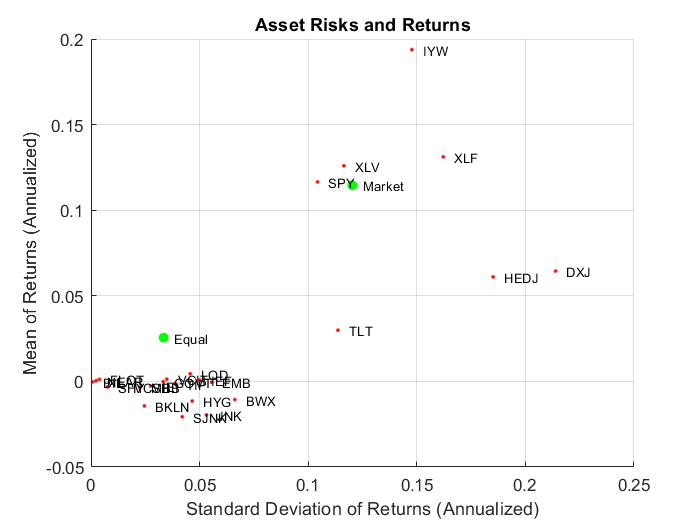

p = Portfolio('Name', 'Conservative' ,'AssetList', AssetList, 'RiskFreeRate', CashReturns(end));
p = p.estimateAssetMoments(AssetReturns,'dataformat', 'returns', 'missingdata', false);

% Set up an equal-weight initial portfolio

p = p.setInitPort(1/p.NumAssets);
[ersk, eret] = p.estimatePortMoments(p.InitPort);

% Plot asset, market, cash, and equal-weight return moments

part1_intro_plot('Asset Risks and Returns', ...
	{'scatter', mrsk, mret, {'Market'}}, ...
	{'scatter', crsk, cret, {'Cash'}}, ...
	{'scatter', ersk, eret, {'Equal'}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});

## Set up a "Standard" Portfolio Optimization Problem based on MPT

Set up a "default" portfolio optimization problem with the `setDefaultConstraints` method that requires fully-invested long-only portfolios (non-negative weights that must sum to 1). Given this initial problem, estimate the efficient frontier with the methods `estimateFrontier` and `estimatePortMoments`, where `estimateFrontier` estimates efficient portfolios and `estimatePortMoments` estimates risks and returns for portfolios. The figure overlays the efficient frontier on the previous plot.

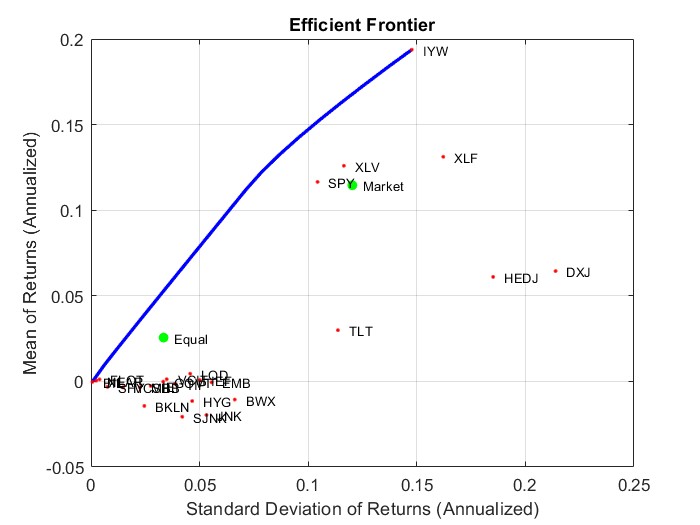

p = p.setDefaultConstraints;
pwgt = p.estimateFrontier(20);
[prsk, pret] = p.estimatePortMoments(pwgt);

% Plot efficient frontier

part1_intro_plot('Efficient Frontier', ...
	{'line', prsk, pret}, ...
	{'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});

## Illustrate the Tangent Line to the Efficient Frontier

Tobin's mutual fund theorem says that the portfolio allocation problem can be viewed as a decision to allocate between a riskless asset and a risky portfolio. In the mean-variance framework, cash serves as a proxy for a riskless asset and an efficient portfolio on the efficient frontier serves as the risky portfolio such that any allocation between cash and this portfolio dominates all other portfolios on the efficient frontier. This portfolio is called a tangency portfolio because it is located at the point on the efficient frontier where a tangent line that originates at the riskless asset touches the efficient frontier.

Given that the Portfolio object already has the risk-free rate, obtain the tangent line by creating a copy of the Portfolio object with a budget constraint that permits allocation between 0% and 100% in cash. This is to setup the efficient forntier and tangent line. Restrictions on cash will be introduced below.  Note that the plot, which shows the efficient frontier with Tobin's allocations includes the tangent line to the efficient frontier.

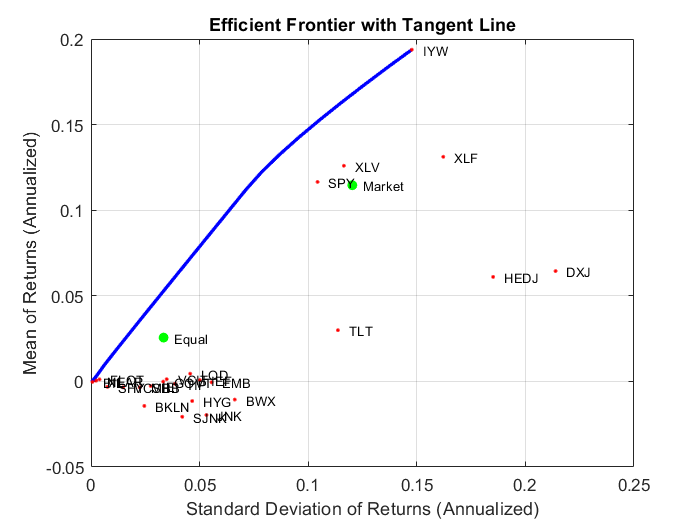

q = p.setBudget(0,1);

qwgt = q.estimateFrontier(20);
[qrsk, qret] = q.estimatePortMoments(qwgt);

% Plot efficient frontier with tangent line (0 to 1 cash)

part1_intro_plot('Efficient Frontier with Tangent Line', ...
	{'line', prsk, pret}, ...
	{'line', qrsk, qret, [], [], 1}, ...
	{'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});

## Obtain Range of Risks and Returns

To obtain efficient portfolios with target values of either risk or return, it is necessary to obtain the range of risks and returns among all portfolios on the efficient frontier. This can be accomplished with the `estimateFrontierLimits` method.

[rsk, ret] = p.estimatePortMoments(p.estimateFrontierLimits);
rsk = sqrt(12)*rsk;
ret = 12*ret;

display(rsk);

rsk =     0.0007
    0.1477


display(ret);

ret =    -0.0001
    0.1938


## Find a Portfolio with a Targeted Return and Targeted Risk

Given the range of risks and returns, demonstrate the location of portfolios on the efficient frontier that have target values for return and risk using the methods `estimateFrontierByReturn` and `estimateFrontierByRisk`.

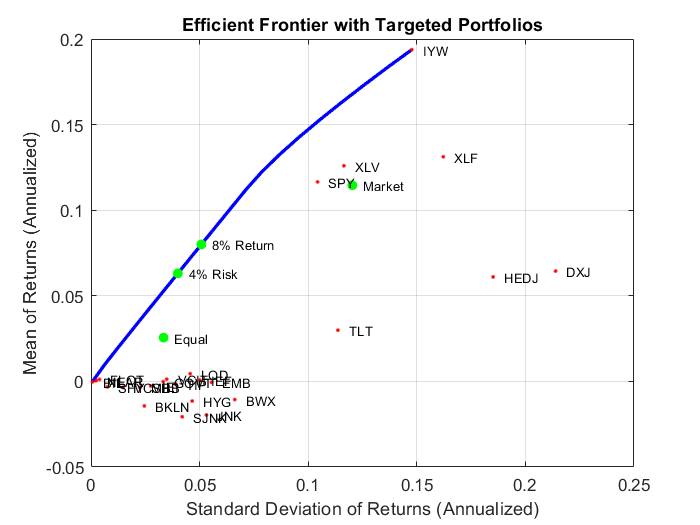

TargetReturn = 0.08;		% input target annualized return and risk here
TargetRisk = 0.04;

if TargetReturn < ret(1) || TargetReturn > ret(2)
	error('TargetReturn is outside current range of available returns [ %g, %g ].', ...
		ret(1), ret(2));
end
if TargetRisk < rsk(1) || TargetRisk > rsk(2)
	error('TargetRisk is outside current range of available risks [ %g, %g ].', ...
		rsk(1), rsk(2));
end	

awgt = p.estimateFrontierByReturn(TargetReturn/12);
[arsk, aret] = p.estimatePortMoments(awgt);

bwgt = p.estimateFrontierByRisk(TargetRisk/sqrt(12));
[brsk, bret] = p.estimatePortMoments(bwgt);

% Plot efficient frontier with targeted portfolios

part1_intro_plot('Efficient Frontier with Targeted Portfolios', ...
	{'line', prsk, pret}, ...
	{'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
	{'scatter', arsk, aret, {sprintf('%g%% Return',100*TargetReturn)}}, ...
	{'scatter', brsk, bret, {sprintf('%g%% Risk',100*TargetRisk)}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});

To see what these targeted portfolios look like, use the dataset object to set up "blotters" that contain the portfolio weights and asset names (which are obtained from the Portfolio object).

aBlotter = dataset({100*awgt(awgt > 0),'Weight'}, 'obsnames', p.AssetList(awgt > 0));

fprintf('Portfolio with %g%% Target Return\n', 100*TargetReturn);

Portfolio with 8% Target Return


disp(aBlotter);

            Weight
    IYW      25.29
    XLF      14.27
    XLV     2.5673
    TLT     29.079
    FLOT    28.794




bBlotter = dataset({100*bwgt(bwgt > 0),'Weight'}, 'obsnames', p.AssetList(bwgt > 0));

fprintf('Portfolio with %g%% Target Risk\n', 100*TargetRisk);

Portfolio with 4% Target Risk


disp(bBlotter);

            Weight    
    IYW         19.877
    XLF         11.213
    XLV         1.9708
    HEDJ    6.4623e-25
    BWX     3.2312e-25
    TLT         23.038
    HYG     1.4109e-24
    LQD     2.0115e-24
    VCSH    2.2122e-25
    VCIT     8.178e-25
    JNK     7.1408e-25
    FLOT        43.901
    SJNK    3.6664e-25
    EMB     1.4232e-24
    SPY     1.6025e-24
    NEAR    1.9582e-24



## Transaction Costs

The Portfolio object makes it possible to account for transaction costs as part of the optimization problem. Although individual costs can be set for each assets, use the scalar expansion features of the Portfolio object's methods to set up uniform transaction costs and compare efficient frontiers with gross versus net portfolio returns.

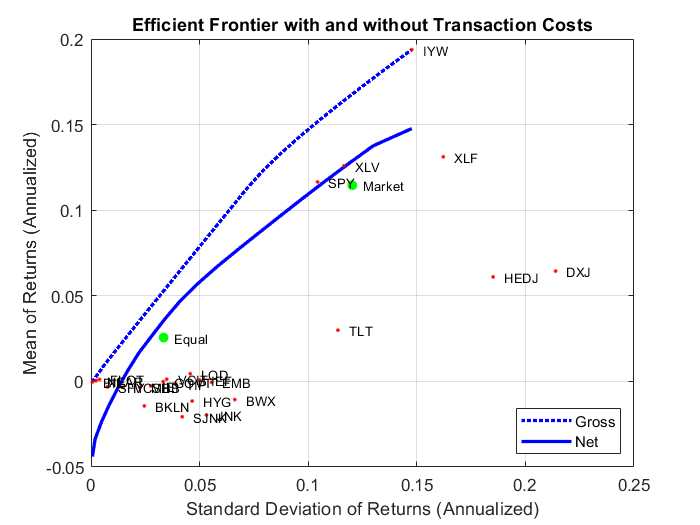

BuyCost = 0.002;
SellCost = 0.002;

q = p.setCosts(BuyCost, SellCost);

[qwgt, qbuy, qsell] = q.estimateFrontier(20);
[qrsk, qret] = q.estimatePortMoments(qwgt);

% Plot efficient frontier with turnover constraint
part1_intro_plot('Efficient Frontier with and without Transaction Costs', ...
	{'line', prsk, pret, {'Gross'}, ':b'}, ...
	{'line', qrsk, qret, {'Net'}}, ...
	{'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});


% disp(sum(qbuy));
% disp(sum(qsell));

## Turnover Constraint

In addition to transaction costs, the Portfolio object can handle turnover constraints. The following example demonstrates that a turnover constraint may prevent a single step from a initial portfolio to the efficient frontier without the turnover constraint. Note that the sum of purchases and sales from the `estimateFrontier` method confirms that the turnover constraint has been satisfied.

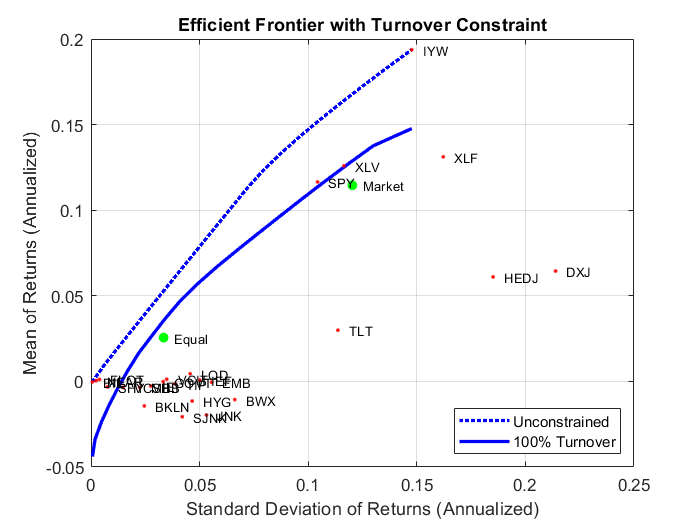

BuyCost = 0.0020;
SellCost = 0.0020;
Turnover = 1.0;

q = p.setCosts(BuyCost, SellCost);
q = q.setTurnover(Turnover);

[qwgt, qbuy, qsell] = q.estimateFrontier(20);
[qrsk, qret] = q.estimatePortMoments(qwgt);

% Plot efficient frontier with turnover constraint

part1_intro_plot('Efficient Frontier with Turnover Constraint', ...
	{'line', prsk, pret, {'Unconstrained'}, ':b'}, ...
	{'line', qrsk, qret, {sprintf('%g%% Turnover', 100*Turnover)}}, ...
	{'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});


% disp(sum(qsell));
% disp(sum(qbuy));

## Establish Equality Portfolio Asset Allocation Constraints

Set minimum equity allocation to 35% for VTI, VEA, and VWO. Represent the constraint in a matrix form

% A = zeros(size(AssetList));

% % First Equality Constraint
% [A] = country_matrix(1,:)
% b = grouped_bonds_percentage(1,1)
% q = q.setInequality(A, b);
% test = [0,1,25];
% 
%   for i= 2:length(grouped_bonds_percentage)
%      [A] = country_matrix(i,:);
%      b = grouped_bonds_percentage(1,i);
%      q = q.addInequality(A, b);
%   end
% 
%   for i = 1:length(grouped_credit_ratings_percentage)
%       [A] = credit_rating_matrix(i, :);
%       b = grouped_credit_ratings_percentage(1,i);
%       q = q.addInequality(A, b);
%   end
% %   
%   for i = 1:length(grouped_years_to_maturity_percentage)
%       [A] = years_to_maturity_matrix(i, :);
%       b = grouped_years_to_maturity_percentage(1,i);
%       q = q.addInequality(A, b);
%   end
% %   
%   for i = 1:length(grouped_currency_percentage)
%       [A] = currency_matrix(i,:);
%       b = grouped_currency_percentage(1,i);
%       q = q.addInequality(A, b);
%   end
% [A] = credit_rating_matrix
% b = grouped_credit_ratings_percentage
% q = q.setInequality(-A, -b);
% 
% for i = 2:length(grouped_credit_ratings_percentage)
%     [A] = credit_rating_matrix;
%     b = grouped_bonds_percentage(1,i);
%     q = setGroups(q, A, 0.0, b);
% end

% G = bonds_country_diag;
% b = 0.35;
% 
% % Set the linear equality constraint
% q = q.setEquality(G,b);


Set Equality Constraint for Credit ETF Exposure (EMB, HYG, LQD) to 17.25%

% A = [0 0 0 1 1 1 0 0 0 0] ; % Second Equality Constraint
% b = 0.1725;
% q = addEquality(q, A, b);
% 
% disp(q.NumAssets);
% disp(q.AEquality);
% disp(q.bEquality);


Set Inequality Constraint for Government Bond & Credit ETF Exposure (BND, BNDx) to 28.25% 

% q = Portfolio(q, 'lowerbound', 0);
% q = Portfolio(q, 'upperbound', 0.2);
%A = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]; % Third Equality Constraint
b = 0.2;
q = setInequality(q, maxAllocation, b);
% 
% disp(q.NumAssets);
% disp(q.AEquality);
% disp(q.bEquality);


Set Equality Constraint for Government Bond ETF Exposure (TLT, TIP) to 19.5%

% A = [0 0 0 0 0 0 0 0 1 1]; % Fourth Equality Constraint
% b = 0.195;
% q = addEquality(q, A, b);
% 
% disp(q.NumAssets);
% disp(q.AEquality);
% disp(q.bEquality);


## Group Constraints for Non- U.S. Dollar Exposure

Set Non-US Dollar exposure to between 0% and 30%

% % We want to limit international, Non-USD exposure, 
% % % For a moderate-conservative portfolio we set the range between 0% and 30% 
% % % Relevant ETFs are VMO, VEA, and BNDx
% % % 
% G = credit_rating_matrix(2,:);
% % % G([ 1 2 7]) = 1;
% % G = [true, true, false, false, false, false, true, false, false, false]
% % 
%  q = addGroups(q, G, 0.0, 0.45);   
% % 
% %  % Display the portfolio object to see the constraints being introduced.
% disp(q);



## Add Budget Consraints

Implementing a long only strategy with no leverage, while also ensuring portfolios are fully invested, and thus have no more than 2% in cash.

q = q.setBudget(0.98, 1); 

disp(q);

  Portfolio with properties:

          BuyCost: [25×1 double]
         SellCost: [25×1 double]
     RiskFreeRate: 0
        AssetMean: [25×1 double]
       AssetCovar: [25×25 double]
    TrackingError: []
     TrackingPort: []
         Turnover: 1
      BuyTurnover: []
     SellTurnover: []
             Name: 'Conservative'
        NumAssets: 25
        AssetList: {1×25 cell}
         InitPort: [25×1 double]
      AInequality: [25×25 double]
      bInequality: [25×1 double]
        AEquality: []
        bEquality: []
       LowerBound: [25×1 double]
       UpperBound: []
      LowerBudget: 0.9800
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []



## Find a Portfolio with a Targeted Return and Targeted Risk Subject to the Above Constraints

Given the range of risks and returns, demonstrate the location of portfolios on the efficient frontier that have target values for return and risk using the methods `estimateFrontierByReturn` and `estimateFrontierByRisk`.

We target a 4.7% return and 3.5 % volatility level for Conservative portfolios. 

It turns out that targeting returns, rather than risk levels, provides a more adequately diversified portfolio of ETFs. 

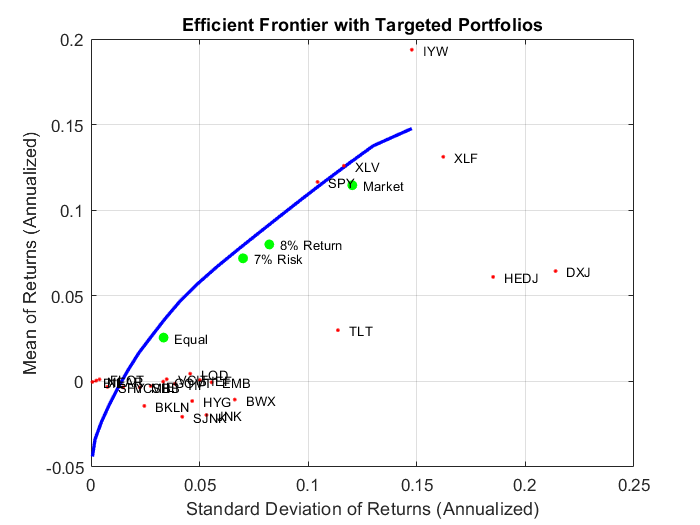

    TargetReturn = 0.08;		% input target annualized return and risk here
    TargetRisk = 0.07;

    if TargetReturn < ret(1) || TargetReturn > ret(2)
	error('TargetReturn is outside current range of available returns [ %g, %g ].', ...
		ret(1), ret(2));
    end
    if TargetRisk < rsk(1) || TargetRisk > rsk(2)
        error('TargetRisk is outside current range of available risks [ %g, %g ].', ...
		rsk(1), rsk(2));
    end	

    awgt = q.estimateFrontierByReturn(TargetReturn/12);
    [arsk, aret] = q.estimatePortMoments(awgt);

    bwgt = q.estimateFrontierByRisk(TargetRisk/sqrt(12));
    [brsk, bret] = q.estimatePortMoments(bwgt);
    
    part1_intro_plot('Efficient Frontier with Targeted Portfolios', ...
        {'line', qrsk, qret}, ...
        {'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
        {'scatter', arsk, aret, {sprintf('%g%% Return',100*TargetReturn)}}, ...
        {'scatter', brsk, bret, {sprintf('%g%% Risk',100*TargetRisk)}}, ...
        {'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});


    % To see what these targeted portfolios look like, use the dataset object to set up "blotters" that
    % contain the portfolio weights and asset names (which are obtained from the Portfolio object).

    aBlotter = dataset({100*awgt(awgt > 0),'Weight'}, 'obsnames', q.AssetList(awgt > 0));

    % fprintf('Portfolio with %g%% Target Return subject with transaction costs and turnover constraints\n', 100*TargetReturn);
    % disp(aBlotter);

    bBlotter = dataset({100*bwgt(bwgt > 0),'Weight'}, 'obsnames', q.AssetList(bwgt > 0));

    fprintf('Portfolio with %g%% Target Risk with transaction costs and turnover constraints\n', 100*TargetRisk);

Portfolio with 7% Target Risk with transaction costs and turnover constraints


    disp(bBlotter);

            Weight    
    IYW             20
    XLF         16.307
    XLV             20
    HEDJ    3.9929e-20
    DXJ     1.6682e-19
    TIP              4
    IEF              4
    IEI              4
    TLT         5.2047
    GOVT             4
    BIL     2.2302e-20
    MBB         1.7711
    HYG     6.6221e-20
    BKLN    1.1248e-19
    LQD              4
    VCSH    1.2647e-19
    VCIT             4
    JNK      4.856e-20
    FLOT             4
    SJNK    2.0839e-20
    SPY         7.0619
    NEAR        1.6554



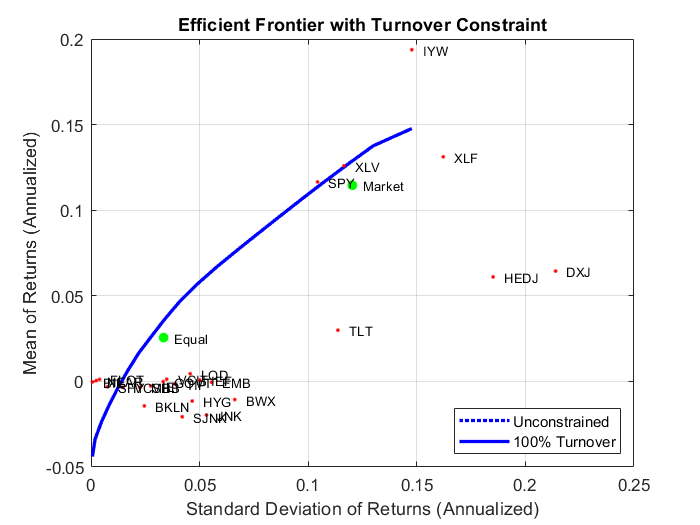


    % Estimate the portfolios in the portfolio frontier with constraints(?)
    [pwgt, pbuy, qsell] = q.estimateFrontier(20);
    [prsk, pret] = q.estimatePortMoments(qwgt);

% Plot efficient frontier with turnover constraint

    part1_intro_plot('Efficient Frontier with Turnover Constraint', ...
	{'line', prsk, pret, {'Unconstrained'}, ':b'}, ...
	{'line', qrsk, qret, {sprintf('%g%% Turnover', 100*Turnover)}}, ...
	{'scatter', [mrsk, crsk, ersk], [mret, cret, eret], {'Market', 'Cash', 'Equal'}}, ...
	{'scatter', sqrt(diag(p.AssetCovar)), p.AssetMean, p.AssetList, '.r'});

Show the Optimized Conservative Portfolio 

To see what these targeted portfolios look like, use the dataset object to set up "blotters" that contain the portfolio weights and asset names (which are obtained from the Portfolio object).

 
    aBlotter = dataset({100*awgt(awgt > 0),'Weight'}, 'obsnames', q.AssetList(awgt > 0));

    fprintf('Conservative Portfolio with %g%% Target Return with all the constraints\n', 100*TargetReturn);

Conservative Portfolio with 8% Target Return with all the constraints


    disp(aBlotter);

            Weight 
    IYW          20
    XLF      15.052
    XLV          20
    TIP     0.94818
    IEF           4
    IEI           4
    TLT           4
    GOVT          4
    LQD           4
    VCIT          4
    SPY          20




    bBlotter = dataset({100*bwgt(bwgt > 0),'Weight'}, 'obsnames', q.AssetList(bwgt > 0));

    fprintf('Conservative Portfolio with %g%% Target Risk with all the contraints\n', 100*TargetRisk);

Conservative Portfolio with 7% Target Risk with all the contraints


    disp(bBlotter);

            Weight    
    IYW             20
    XLF         16.307
    XLV             20
    HEDJ    3.9929e-20
    DXJ     1.6682e-19
    TIP              4
    IEF              4
    IEI              4
    TLT         5.2047
    GOVT             4
    BIL     2.2302e-20
    MBB         1.7711
    HYG     6.6221e-20
    BKLN    1.1248e-19
    LQD              4
    VCSH    1.2647e-19
    VCIT             4
    JNK      4.856e-20
    FLOT             4
    SJNK    2.0839e-20
    SPY         7.0619
    NEAR        1.6554



## References

- R. C. Grinold and R. N. Kahn, Active Portfolio Management, 2nd ed., 2000.

- H. M. Markowitz, ?Portfolio Selection,? Journal of Finance, Vol. 1, No. 1, March 1952, pp. 77-91.

- H. M. Markowitz, Portfolio Selection: Efficient Diversification of Investments, John Wiley & Sons, Inc., 1959.

- W. F. Sharpe, ?Mutual Fund Performance,? Journal of Business, Vol. 39, No. 1, Part 2, January 1966, pp. 119?138.

- J. Tobin, "Liquidity Preference as Behavior Towards Risk," Review of Economic Studies, Vol. 25, No.1, 1958, pp. 65-86.

- J. L. Treynor and F. Black. ?How to Use Security Analysis to Improve Portfolio Selection,? Journal of Business, Vol. 46, No. 1, January 1973, pp. 68-86.